# Modeling uncertain systems with the Ulft class

The Ulft class is the central class for modeling uncertain and nonlinear systems. Objects of this class are passed to the iqcAnalysis function in order to assess robustness properties of the uncertain and nonlinear system. After this script, you will understand what an LFT is, how it is represented with the `Ulft` class, and how to create and combine `Ulft` objects.

## Very brief theoretical background

A Ulft class expresses what are called *linear fractional transformations (LFTs) *of an uncertain and nonlinear system. In this context, LFTs are an interconnection of an certain, linear, "nominal" system M, and a possibly nonlinear, uncertain, "troublesome" operator Delta.


$$e = (M, \Delta)(d) \Leftrightarrow 
\matrix{ \phi & = & \Delta(\theta) \cr
     \theta & = & M_{11} \phi + M_{12} d \cr
     e & = & M_{21} \phi + M_{22} d
}$$


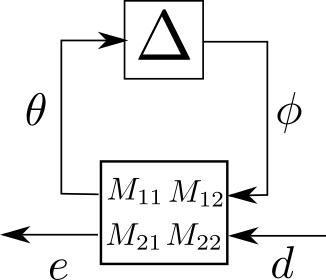

A rational transfer matrix may be represented as an LFT, where the state-evolution operator (either delay for discrete-time or integration for continuous-time) is the Delta block, and M11, M12, M21, and M22 are the `a`, `b`, `c`, and `d` matrices (respectively) for a realization of the transfer function.

gc = rss()
gc_lft = toLft(gc)
gd = drss()
gd_lft = toLft(gd)

Here you can see that the number of states in `gc` and `gd` are reflected in the displayed size of `gc_lft.delta` and `gd_lft.delta`, respectively.  Also, the `a, b, c, d` matrices of the `ss` object and the `Ulft` object match.

gc.a - gc_lft.a{1}

The Delta operator can contain far more than the state-evolution operator though.  It most often has numerous operators which represent additional uncertainties and nonlinearities that are presented in a block diagonal structure:

For example, if the transfer function `gd` is premultiplied by an unknown, time-invariant scalar $\delta \in [0.9, 1.1]$, this (now uncertain) system could be represented with:

del1 = DeltaSlti('del1', size(gd_lft, 2));
gd_uncertain = gd_lft * del1

Now we see that the uncertain transfer function has two deltas: `DelayZ`, and `del1`. 

In this toolbox, even though the state-evolution operators are technically known, we lump them into the Delta block for convenience. Because of this, we use the fields `a, b, c,` and `d` to represent the $M_{11}, \ M_{12}, \ M_{21}, \mbox{ and }  \ M_{22}$ blocks in the equations and block diagram above.

LFTs (we use the class name `Ulft` for *upper *LFTs) are useful to model uncertain and nonlinear systems, because (1) they have a clean separation between the known and the troublesome components of a system and (2) they compose together rather easily.  In other words, you don't need to know how to define the `a, b, c,` and `d` matrices of complicated uncertain systems. This will generally be done with simple operations, such as multiplication and addition.

## How do I make an LFT?

### The `Ulft()` constructor

`Ulft` objects require 5 arguments at a minimum: the `a, b, c,` and `d` matrix, as well as the pertinent `delta` object. For example:

dim_state = size(gc.a, 1);
integrator = DeltaIntegrator(dim_state);
gc_lft2 = Ulft(gc.a, gc.b, gc.c, gc.d, integrator)

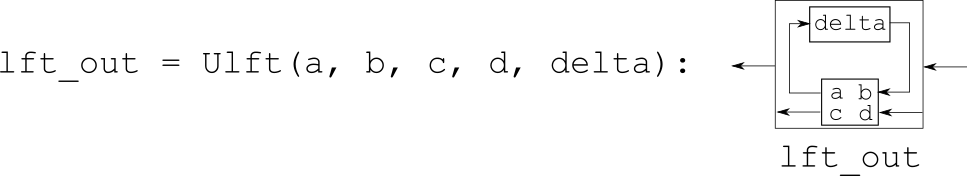

### The `toLft()` helper function

This construction requires the `a, b, c,` and `d` matrices, along with the `delta` block (per the block diagram above). The helper function `toLft()` can convert non-Ulft objects into `Ulft` objects.  For example, a matrix can be expressed as an LFT:

lft_eye = toLft(eye(3))

Or a state-space system:

g_ss = rss();
lft_ss = toLft(g_ss)

Or any Delta operator:

del = DeltaSlti('del') % A 1 x 1 static, linear, time-invariant uncertainty within the range [-1, 1]
lft_del = toLft(del) % The equivalent Ulft

State-space systems can also be expressed as `Ulft` objects following the same syntax as `ss` objects.

g_ss_2   =    ss(g_ss.a, g_ss.b, g_ss.c, g_ss.d)
lft_ss_2 = toLft(g_ss.a, g_ss.b, g_ss.c, g_ss.d)

### Converting between Robust Control Toolbox and iqcToolbox -- `rctToLft()` and `lftToRct()` 

You can also convert from `umat `and `uss` objects to `Ulft` objects:

rct_umat = umat(randatom('ureal'));
lft_umat = rctToLft(rct_umat)
rct_uss = rss(2, 1, 1) * rct_umat;
lft_uss = rctToLft(rct_uss)

*NOTE:*

`Delta`* objects obtained from *`rctToLft` *are typically normalized representations of the *`ureal ``or ``ultidyn `*objects. These normalized objects are such that the *`Ulft` *is an equivalent representation of the *`umat` or `uss `*when the uncertainties are evaluated to their normalized values.*

And `Ulft` objects can be converted to `uss` objects:

rct_uss_2 = lftToRct(lft_uss) % Convert the lft back to a uss object

*NOTE:*

*Currently, conversions between the iqcToolbox uncertainties and the Robust Control Toolbox uncertainties are as follows:*

`Robust Control Toolbox  |  iqcToolbox`

`ureal                <-----> DeltaSlti`

`ultidyn              <-----> DeltaDlti`

`umargin               -----> Unsupported`

`ucomplex              -----> Unsupported`

`udyn                 <-----  Any other Delta object (except for DeltaIntegrator and DeltaDelayZ)`

### Generating Random LFTs -- `Ulft.random()`

The convenience method `Ulft.random()` allows us to generate a random LFT.  Though they are typically not robustly stable, every dynamic LFT (i.e., with either a `DeltaIntegrator` or `DeltaDelayZ` block) is nominally stable.

lft_rand = Ulft.random()

You can specify constraints that the randomly generated LFT must satisfy.  The constraints include:

-  the number of Deltas, 

- the required types of Deltas, 

- specific Deltas that must be included, 

- input dimensions, 

- output dimensions, and 

- the `horizon_period` of the LFT (`horizon_period` is described in a latter section).  

For example, if we want a LFT with 2 input channels, 3 output channels, 3 Delta blocks (one of which can be anything, another must be a random `DeltaSlti` object, and the last must be a predefined `del)`, we could do the following:

del = DeltaBounded('del'); % Create a 1 x 1 bounded Delta with l2-induced norm <= 1
lft_rand_2 = Ulft.random('num_deltas', 3, 'req_deltas', {'DeltaSlti', del}, 'dim_out', 3, 'dim_in', 2)

### Composing LFTs from other LFTs 

`Ulft()`, `toLft()`, and `rctToLft() `create LFTs. These LFTs can then be composed together to generate more LFTs.  For example, if you wanted to create an uncertain matrix:


$$X = \left[\matrix{p & qr \cr 0 & 3 - p}\right] = \left[\matrix{0 & 0 \cr 0 & 3}\right] + \left[\matrix{p & 0 \cr 0 & -p}\right] + \left[\matrix{0 & qr \cr 0 & 0}\right], \ \mbox{ where } 
\ \ \matrix{p,q \in [-0.5, 0.5]  \  \mbox{ are time-varying} \cr
r \in [4, 7] \ \mbox{is time-invariant}}$$


dim_outin = 1;
p = DeltaSltv('p', dim_outin, -.5, .5); % Create uncertainty p
q = DeltaSltv('q', dim_outin, -.5, .5); % Create uncertainty q
r = DeltaSlti('r', dim_outin, 4, 7); % Create uncertainty r
mat1 = [0, 0; 
        0, 3];
mat2 = [p, 0;
        0, -p];
mat3 = [0, q * r;
        0,     0];
X = mat1 + mat2 + mat3

Or:

X2 = [p, q * r;
      0, 3 - p]

This uncertain matrix could then be used to define, for example, an uncertain matrix in a state-space system. Recall that a state-space system can be expressed as an LFT:

g_ss = drss(2, 2, 2); % A state-space system
g_lft = toLft(g_ss.a, g_ss.b, g_ss.c, g_ss.d, g_ss.Ts) % A Ulft object of the same system

Suppose then that `b` matrix of this state-space system is actually the uncertain matrix `X`.  This can be expressed with the following:

g_unc = toLft(g_ss.a,      X, g_ss.c, g_ss.d, g_ss.Ts) % An uncertain state-space system

And this uncertain `Ulft` could be pre-multiplied with another uncertainty:

del = DeltaPassive('del', size(g_unc, 1));
g_unc_del = g_unc * del

`Ulft` objects can be multiplied, added, subtracted, inverted (if invertible), horizontally concatenated, and vertically concatenated. These operations enable the creation of a single `Ulft` from complicated block-diagrams of many smaller `Ulft` objects.

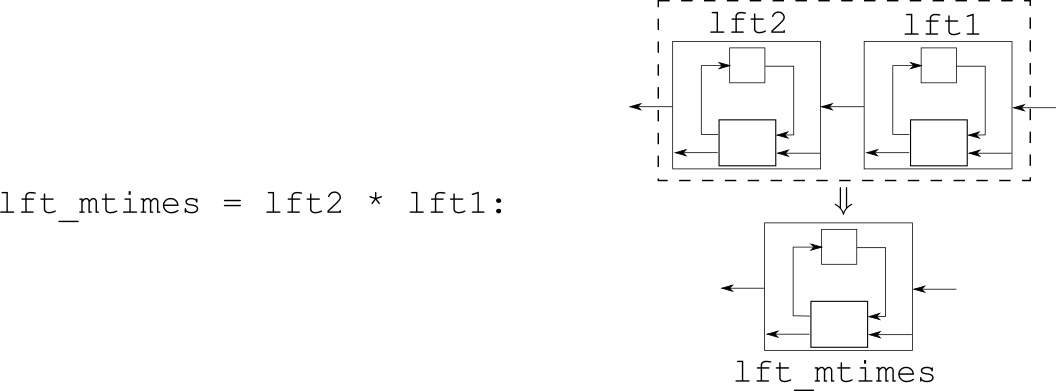

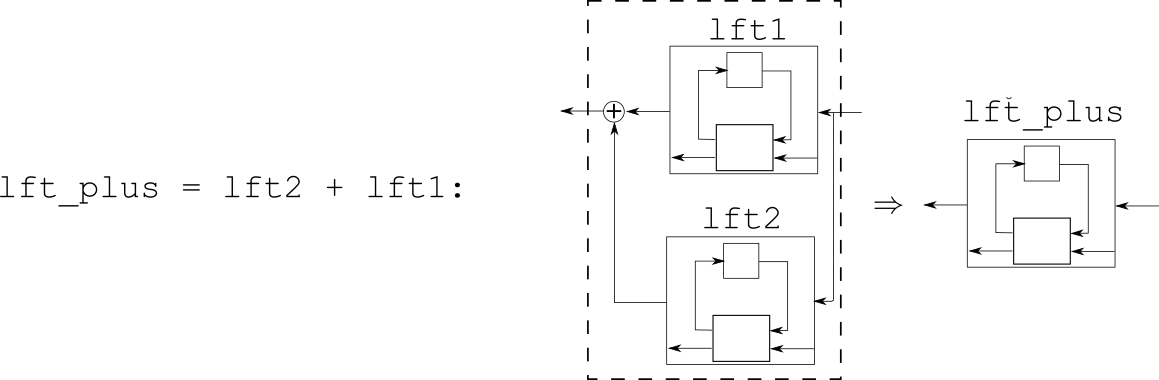

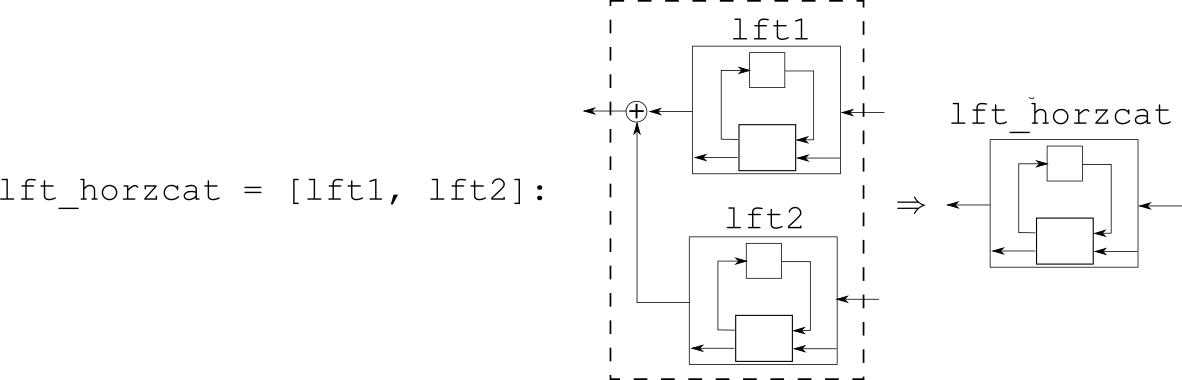

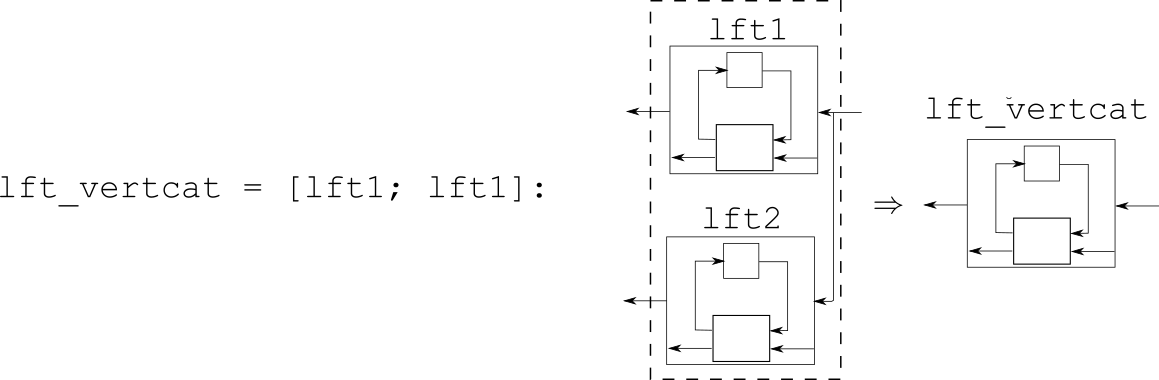

Another important operation for combining `Ulft` objects is defined by the `interconnect` method:

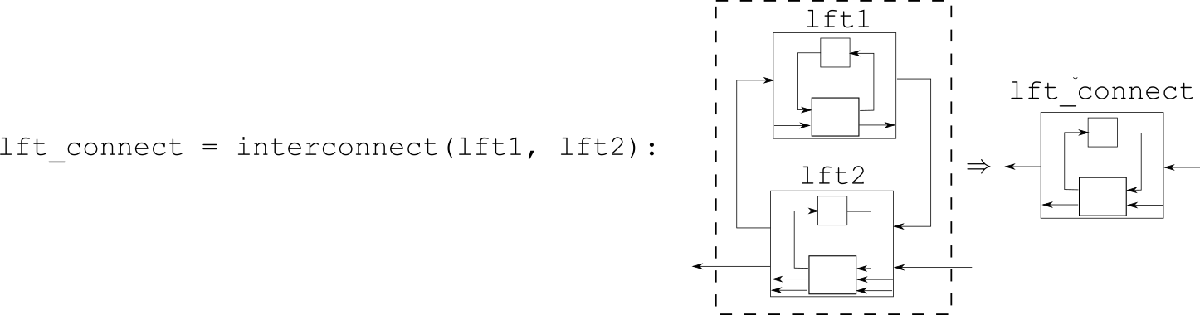

## Additional properties of `Ulft` objects

Till now, we've only discussed the `a`, `b`, `c`, `d`, and `Delta` blocks that express an LFT. However, there are additional `Ulft` properties: `horizon_period`, `disturbance`, and `performance`. Those can be specified in the constructor call:

g_ss = rss();
del = DeltaIntegrator(size(g_ss.a, 1));
horizon_period = [0, 1];
perf = PerformancePassive('passive');
dis = DisturbanceTimeWindow('window');
g_lft = Ulft(g_ss.a, g_ss.b, g_ss.c, g_ss.d, del,...
             'horizon_period', horizon_period,...
             'performance', perf,...
             'disturbance', dis)

More details on an LFTs `performance` and `disturbance` properties are discussed in their own sections.  Here we will only discuss `horizon_period.`

### What is the `horizon_period `of an LFT?

iqcToolbox is capable of analyzing discrete-time time-varying systems. These time-varying systems may be periodic, or finite-horizon, or (more generally) eventually-periodic.  The `horizon_period` of an LFT is used to express its eventually-periodic properties.

#### What is an eventually-periodic LFT?

Given a sequence of matrices $\{X_i\}_{i\in[0, \infty)$, the sequence is `[h, q]`-eventually periodic if $X_{h+j} = X_{h + j + q} \ \mbox{ for all} \ j \in [0, \infty)$. 

In other words, a sequence is `[h, q]`-eventually periodic if, after `h` timesteps, the sequence becomes periodic with a period of `q` timesteps.  A time-varying LFT is `[h, q]`-eventually periodic if each of it's sequences of `a`, `b`, `c`, and `d` matrices are `[h, q]`-eventually periodic.

For example, a `[0, 1]`-eventually periodic system is simply time-invariant; it has a no horizon `h`, and it has a period of `1`. It's `horizon_period` would be `[0, 1]. `This is the "trivial" `horizon_period`, and the default assumption if unspecified in the `Ulft()` constructor.

A periodic system with period `3` is `[0, 3]`-eventually periodic. It's `horizon_period` is `[0, 3]`.

A finite horizon system whose dynamics are expressed in the first `5` timesteps is `[5, 1]`-eventually periodic. After the first `5` timesteps, the system matrices are set to zeros and become periodic with period `1. `The `horizon_period` of this system is `[5, 1].`

*NOTE:*

*Deltas which are NOT [h, q]-eventually periodic (for example, an arbitrarily time-varying parameter) can still be incorporated in [h, q]-eventually periodic LFTs. Eventual-periodicity expresses the behavior of the a, b, c, d, matrices of the LFT.  There are, however, properties of Deltas, Disturbances, and Performances, which ARE eventually periodic, but those are generally handled in the background (unless users want to exploit that feature).*

*NOTE:*

*Eventual-periodicity is only well-defined for discrete-time systems. iqcToolbox does not currently support time-varying continuous-time systems.*

#### Combining objects with different `horizon_period`

Suppose you wish to combine two different LFTs whose `horizon_period` differ.

lft_rand = Ulft.random('dim_out', 1, 'dim_in', 1, 'horizon_period', [3, 2]);
constant = toLft(1);
lft_rand.horizon_period
constant.horizon_period

This is allowable because a sequence's `horizon_period` is non unique (for example, a `[1, 1]`-eventually periodic system is also `[1, 2]`-eventually periodic, and `[1, 3]`-eventually periodic, and so on), and because two sequences always share a common `horizon_period`. Whenever combining two LFTs, a common `horizon_period` is identified, both objects are re-expressed in that common `horizon_period`, and the two LFTs can be combined. This typically occurs in the background:

lft_combined = lft_rand + constant;
lft_combined.horizon_period

However, there may exist times when you need to make such transformations manually.  This can be done with the function `commonHorizonPeriod `and the method `matchHorizonPeriod`:

new_hp = commonHorizonPeriod([lft_rand.horizon_period;
                              constant.horizon_period])
lft_rand = matchHorizonPeriod(lft_rand, new_hp); 
constant = matchHorizonPeriod(constant, new_hp);
lft_combined_2 = lft_rand + constant;
lft_combined_2.horizon_period